**Př. 6.:** Funkce náhodné číslo generuje data z rovnoměrného rozdělení s parametry a=0, b=1. Transformujte tato data tak, aby a=10 a b=15. Tj. byla rovnoměrně rozdělena mezi <10,15>

a = 10
b = 15
x = 0.5

y = (b - a) * x + a

**Př. 12.:** Doba do poruchy zařízení lze popsat exponenciálním rozdělením. Data o poruchách máte uvedeny v souboru P0512.mat. Vypočtěte parametry exponenciálního rozdělení a střední dobu do poruchy

x = importdata("P0512.mat")
h = expfit(x)
lambda = 1 / h

**Př. 13:** Doba do poruchy zařízení je popsána exponenciálním rozdělením, kde střední doba do poruchy E(T)=2000 h. Vygenerujte 10, 100 a 1000 dat z tohoto rozdělení a vypočtěte z dat střední hodnotu a rozptyl. Všimněte si, že pravděpodobně 1000 vstupních dat bude mít nejblíže k střední hodnotě 2000 h. 

Pro vektor 1000 dat vypočtěte medián. Všimněte si, že medián není roven střední hodnotě. 


for index = 1:3
    data = exprnd(2000, [1 10^index]);
    stredni = mean(data)
    rozptyl = var(data)
    med = median(data)
    disp("=====")
end

stredni = 1.4318e+03

rozptyl = 1.3846e+06

med = 1.0447e+03

=====


stredni = 1.9372e+03

rozptyl = 4.6004e+06

med = 1.3518e+03

=====


stredni = 2.0128e+03

rozptyl = 3.7687e+06

med = 1.3659e+03

=====


`Příklad 15 ``Doba opravy má exponenciální rozdělení. Určete střední dobu opravy, jestliže do 60 minut je opraveno 30 % výrobků`

lambda = 0.3/60

lambda = 0.0050


[m, v] = expstat(lambda)

m = 0.0050

v = 2.5000e-05

**Př. 21**.: Zjistěte z dat o poruchovosti výrobku, které jsou uloženy v souboru P0521.mat, parametry Weibullova rozdělení.

x = importdata("P0521.mat")

x =   317.2873
  144.0729
  216.7932
  263.5199
  214.6021
  233.6350
  245.4773
  227.7269
  159.4188
  251.1932


t = wblfit(x)

t =   269.4155    5.4606


**Př. 21b**.: Testuje se životnost 100 výrobků. Doba zkoušky trvá 10000 hodin. Celkem bylo zaznamenáno 79 poruch. Výrobky po poruše nejsou nahrazeny novými. V čase 10000 hodin je zkouška ukončena (21 výrobků). Určete parametry Weibullova rozdělení. Vstupní data viz soubor P0521b.xlsx

x = importdata("P0521b.xlsx").List1

x = 1.0e+03 *

    0.1200
    0.1540
    0.1870
    0.2120
    0.2540
    0.2680
    0.4610
    0.5120
    0.5640
    0.5680


cens(1:79) = 0;
freq(1:79) = 1;
x(80) = 10000;
cens(80) = 1;
freq(80) = 21;

t = wblfit(x, 0.05, cens, freq)

Error using wblfit
X and CENSORING must have the same
size.

**Př. 22:: **Nakreslete graf, kde budou vyneseny hustoty pravděpodobnosti z normálního rozfdělení s následujícími parametry:

x = -10:0.1:10

x =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


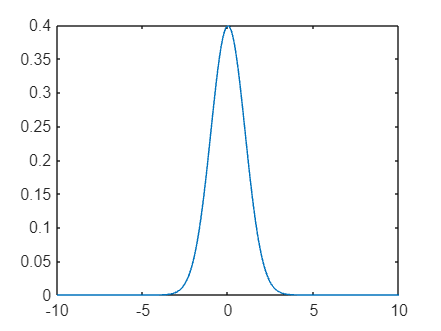

plot(x, normpdf(x, 0, 1))

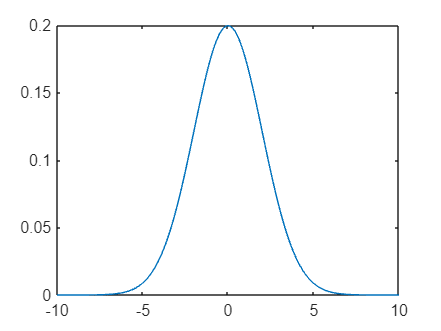

plot(x, normpdf(x, 0, 2))

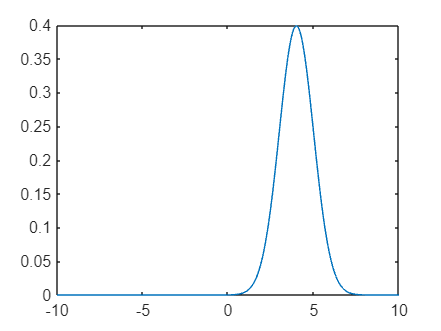

plot(x, normpdf(x, 4, 1))

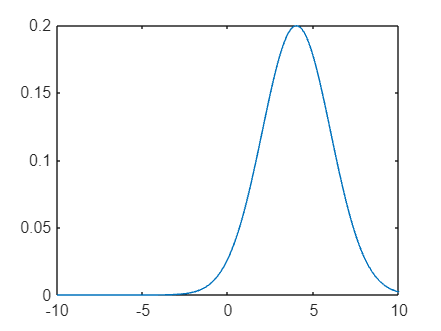

plot(x, normpdf(x, 4, 2))

**Př. 24.:** Máte normální rozdělení s parametry N(5, 2^2). Vypočtete následující hodnoty:

x = -10:0.1:10

x =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000



mi = 5

mi = 5

sigma_kvadrat = 4

sigma_kvadrat = 4


% 20% kvantil
a = norminv(0.2, 5, sqrt(sigma_kvadrat))

a = 3.3168

% 50% kvantil
norminv(0.5, 5, sqrt(sigma_kvadrat))

ans = 5

% Ze znalosti výsledku z bodu a) zpaměti 80% kvantil
mi * 2 - a

ans = 6.6832

% F(x = 3.5)
d = normcdf(3.5, 5, sqrt(sigma_kvadrat))

d = 0.2266

% F(x = 8)
normcdf(8, 5, sqrt(sigma_kvadrat))

ans = 0.9332

% Z paměti ze znalosti výsledku z bodu d) F(x=6.5)
1 - d

ans = 0.7734

**Př. 26.: **Výsledky měření jsou zatíženy jen normálně rozdělenou náhodnou chybou se směrodatnou odchylkou 3mm

- Jaká je pravděpodobnost, že při měření bude chyba v intervalu (-2 mm, 5 mm)

- Máte 3 výrobky, jaká je pravděpodobnost, že alespoň u jednoho výrobku bude chyba mimo tento interval

% a

a = 0.6997

a = normcdf(5, 0, 3) - normcdf(-2, 0, 3)
% b

ans = 0.6574

binocdf(2, 3, a)

**Př. 31.:** Pravděpodobnost, že náhodná veličina nabude vyšší hodnoty než 59.6 je 0.2119. Pravděpodobnost, že nabude hodnoty menší než 57.2 je 0.7258. Náhodná veličina je z normálního rozdělení. Vypočtěte hodnoty parametrů.

% Normované normální rozdělení

ans = 0.6002

a = norminv(0.7258, 0, 1)

ans = 0.7998

b = norminv(1 - 0.2119, 0, 1)

% 0.6 = 57.2 - mi / sigma
% 0.8 = 59.6 - mi / sigma